filename = 'turkish_poems.csv';
filename_stopwords = 'stopwords-tr.json';
pythonpath = ('/Library/Frameworks/Python.framework/Versions/3.12/bin/python3.12');
pe = pyenv('Version',pythonpath);
py.importlib.import_module('snowballstemmer');
%We introduce the necessary edits into dataset such as categorical.
poemsdata = readtable(filename,'TextType','string');
head(poemsdata)

                 poem_name                        poet_name                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           

poemsdata.poet_name = categorical(poemsdata.poet_name);
categories(poemsdata.poet_name);

%To create sufficient and efficient bar graph we do such arrangements into
%data set and listing the poets by highest to lowest written poems.
poetsdata = groupsummary(poemsdata,"poet_name");
poetsdata = poetsdata(poetsdata.GroupCount >= 3, :);
poetsdata.poet_name = removecats(poetsdata.poet_name);
poetsdata_descending = sortrows(poetsdata,'GroupCount','descend');
[~,idx] = sort(poetsdata.GroupCount,'descend');
new_Order = cellstr(string(poetsdata.poet_name(idx)));
poetsdata.poet_name = reordercats(poetsdata.poet_name,new_Order);

% Bunch of codes to create the appropriate readable and meaningful graph
poetbar = bar(poetsdata.poet_name(idx),poetsdata.GroupCount(idx))

poetbar =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [Nazım Hikmet Ran    Necip Fazıl Kısakürek    Attila İlhan    Cemal Safi    Can Yücel    Özdemir Asaf    Orhan Veli Kanık    Ahmed Arif    Mevlana Celaleddin Rumi    Mehmet Akif Ersoy    Yusuf Hayaloğlu    …    ] (1×29 categorical)
        YData: [58 56 50 38 34 32 29 28 24 19 18 9 8 6 6 6 6 5 5 5 5 5 4 4 3 3 3 3 3]

  Show all properties


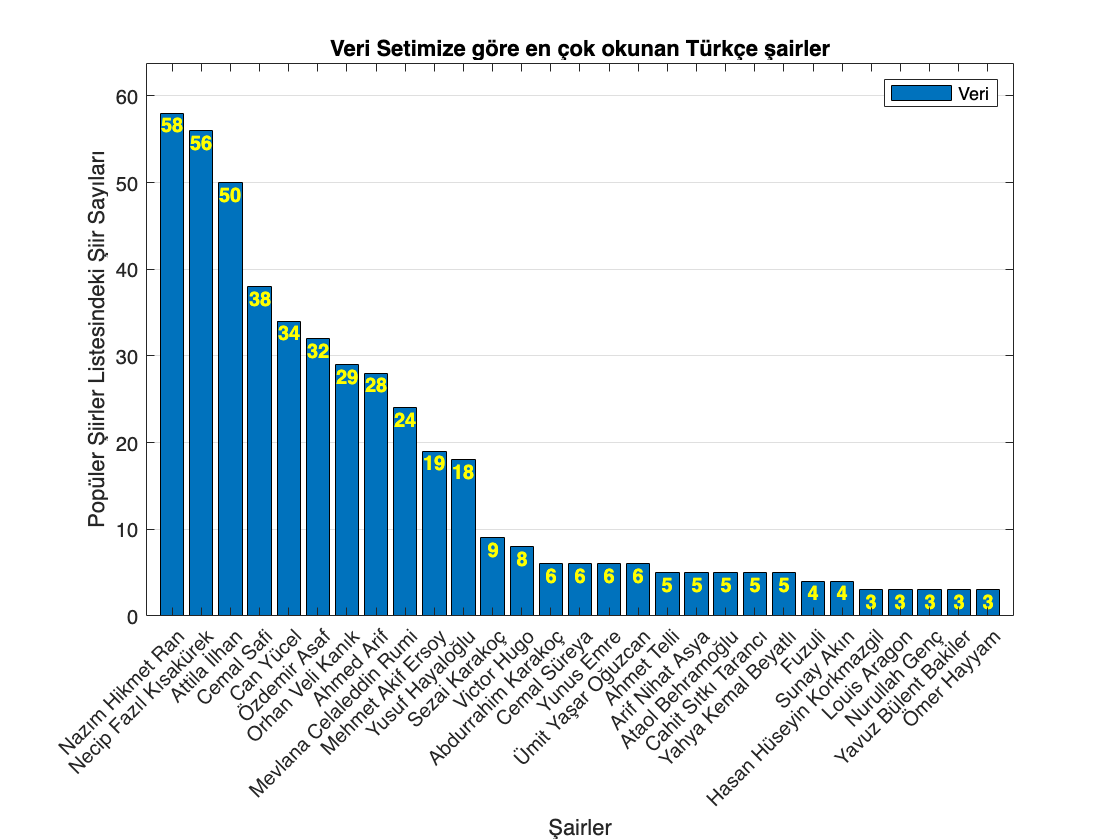

set(gca, 'XTickLabel', poetsdata.poet_name(idx), ...
         'XTickLabelRotation', 45, ...       % to show titles in perpendicular degree
         'XGrid', 'off', 'YGrid', 'on');
xlabel('Şairler');
ylabel('Popüler Şiirler Listesindeki Şiir Sayıları');
title('Veri Setimize göre en çok okunan Türkçe şairler');
legend('Veri');
set(gca, "XGrid", "off", "YGrid", "on");
ylim([0,1.1*max(poetsdata.GroupCount)]);
counts = poetsdata.GroupCount(idx); % to write down the numbers of written poems by every poets
xt = poetbar.XEndPoints;
yt = poetbar.YEndPoints;
text(xt,yt, string(counts),...
    'HorizontalAlignment','center',...
    'VerticalAlignment', 'top',...
    'FontWeight','bold','Color','y');

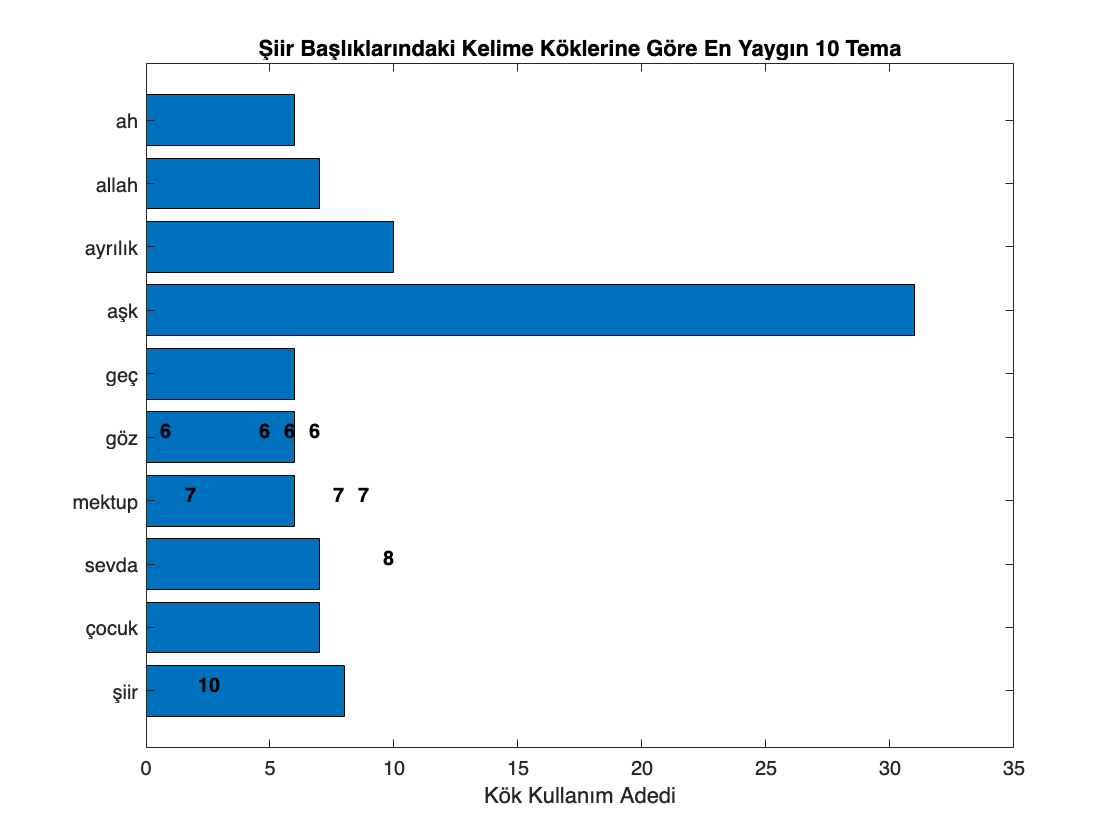

%tokenize the titles of the poem and the text accordingly and also
%processing the data
[poemtitles, poemwritten] = deal(poemsdata.poem_name, poemsdata.poem_text);
[poemtitles_tzd, poemwritten_tzd] = deal(tokenizedDocument(poemtitles), tokenizedDocument(poemwritten));
[poemtitles_tzd, poemwritten_tzd] = deal(lower(poemtitles_tzd), lower(poemwritten_tzd));
[poemtitles_tzd, poemwritten_tzd] = deal(erasePunctuation(poemtitles_tzd), erasePunctuation(poemwritten_tzd));
% At the beginning we introduce python environment to MATLAB due to the
% lack of native support of MATLAB to Turkish Language, instead we turn our
% face into snowballstemmer library, rather slow compared to pystemmer yet
% saves the day
stopwords_docs = fileread(filename_stopwords);
stopwords = jsondecode(stopwords_docs);
stemmer = py.snowballstemmer.stemmer('Turkish');

% To find out and listing the stem of the each words in poem TITLES, bunch
% of python compatibility requirement is also satisfied.
counttitles= numel(poemtitles_tzd);
procCell = cell(counttitles,1);
for i = 1:counttitles
    tokens = poemtitles_tzd(i).Vocabulary;
    tokens = setdiff(tokens, stopwords, 'stable');
    tokensCell = cellstr(tokens);
    pyList = py.list(tokensCell);
    stemsPy = stemmer.stemWords(pyList);
    stemsCell = cellfun(@char, cell(stemsPy),'UniformOutput',false);
    procCell{i} = strjoin(stemsCell,' ');
end  

processed_Strings = string(procCell);
processed_poemtitles_tzd = tokenizedDocument(processed_Strings);
wordsbag = bagOfWords(processed_poemtitles_tzd);
terms = wordsbag.Vocabulary;

% To prepare the graph
frequencywords = sum(wordsbag.Counts,1);
[~, idf] = sort(frequencywords, 'descend');
topwords = 10;
idxTop = idf(1:topwords);
vals = full(frequencywords(idxTop));      
figure
themebarh = barh(categorical(terms(idxTop)), vals);
set(gca,'YDir','reverse','GridLineStyle','--');
xlabel('Kök Kullanım Adedi');
title(sprintf('Şiir Başlıklarındaki Kelime Köklerine Göre En Yaygın %d Tema', topwords));
xtf = themebarh.XEndPoints;
ytf = themebarh.YEndPoints;
text( xtf, ytf, string(vals), ...
      'HorizontalAlignment','right', ...
      'VerticalAlignment','baseline', ...
      'FontWeight','bold', ...
      'Color','k' );

%Doing the same job for Poem Text like done in Poem Titles
poemwritten_tzd = removeWords(poemwritten_tzd, string(stopWords));
count_writtentexts = numel(poemwritten_tzd);
procCell2 = cell(count_writtentexts,1);
for texts = 1:count_writtentexts
    tokenstexts = poemwritten_tzd(texts).Vocabulary;
    tokenstexts = setdiff(tokenstexts, stopwords, 'stable');
    tokenstexts_cell = cellstr(tokenstexts);
    pyList_texts = py.list(tokenstexts_cell);
    stemsPy_texts = stemmer.stemWords(pyList_texts);
    stemstext_Cell = cellfun(@char, cell(stemsPy_texts),'UniformOutput', false);
    procCell_Texts{texts} = strjoin(stemstext_Cell, ' ');
end
Processed_Text_Strings = string(procCell_Texts);
Processed_Poemtexts = tokenizedDocument(Processed_Text_Strings);


textswordsbag = bagOfWords(Processed_Poemtexts);
NumberTopics = 10

NumberTopics = 10

mdl = fitlda(textswordsbag,NumberTopics,...
    'Verbose',0,...
    'IterationLimit', 500);
NumberofWordsforTopic = 15;
topicvocabulary = mdl.Vocabulary;
probabilityMatrix = mdl.TopicWordProbabilities;

topTermsPerTopic = strings(NumberTopics, NumberofWordsforTopic)

topTermsPerTopic = 10×15 string array
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""
    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""    ""


for k = 1:NumberTopics
    [sortedProbs, sortedIdk] = sort(probabilityMatrix(:,k), 'descend');
    topIdk = sortedIdk(1:NumberofWordsforTopic);
    topTermsPerTopic(k, :) = topicvocabulary(topIdk);
    fprintf("Konu %d: %s\n", k, strjoin(topTermsPerTopic(k,:), ', '))
end

Konu 1: yer, el, göz, et, ey, dudak, akl, ev, mi, ca, i, bakar, bir, kar, t
Konu 2: yürek, yol, var, an, yüz, ak, ad, dünya, saç, üst, kız, yaz, ol, kol, ayrılık
Konu 3: el, düş, der, kal, git, duvar, dil, hayat, zama, yaş, sevda, ar, eski, değil, ya
Konu 4: geç, kar, yıldız, allah, göz, alt, ön, ah, son, öl, gönl, gör, dedi, bugu, büyük
Konu 5: çocuk, gün, yüz, ar, be, bak, diyor, söz, güneş, gelir, güzel, dur, g, k, bilir
Konu 6: toprak, gel, de, gök, se, taş, yol, ayak, yan, ateş, yer, ay, yıl, ne, yar
Konu 7: baş, aşk, ağaç, başka, bahçe, ol, yok, zama, mi, ya, rüya, dol, hal, dal, ardı
Konu 8: su, iç, al, dak, gün, baş, yer, sabah, bulut, i̇ç, kalp, el, yağmur, yeşil, or
Konu 9: göz, iç, gül, kan, karanlık, uzak, kuş, öl, güzel, in, sokak, ışık, gönül, kendi, ruh
Konu 10: ses, dünya, rüzgar, üst, çiçek, aç, ş, baş, ver, gökyüz, yar, de, akşa, kitap, gel


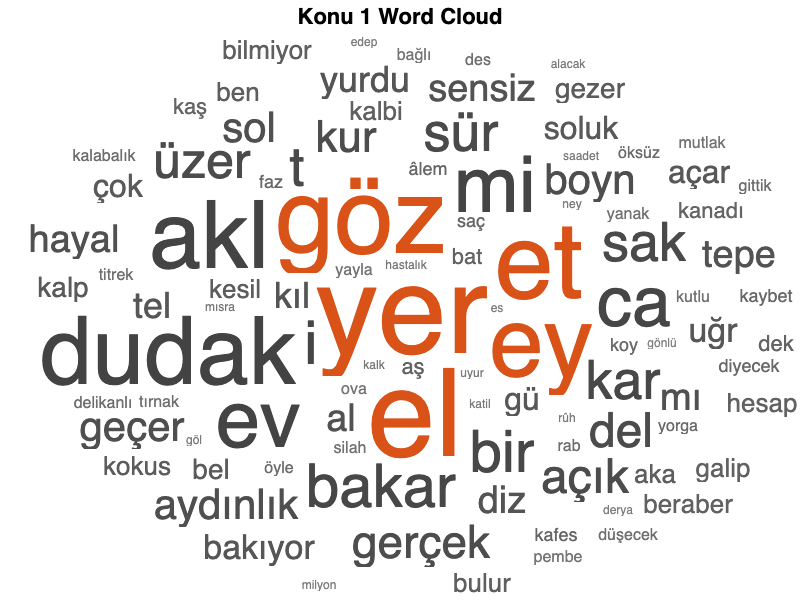

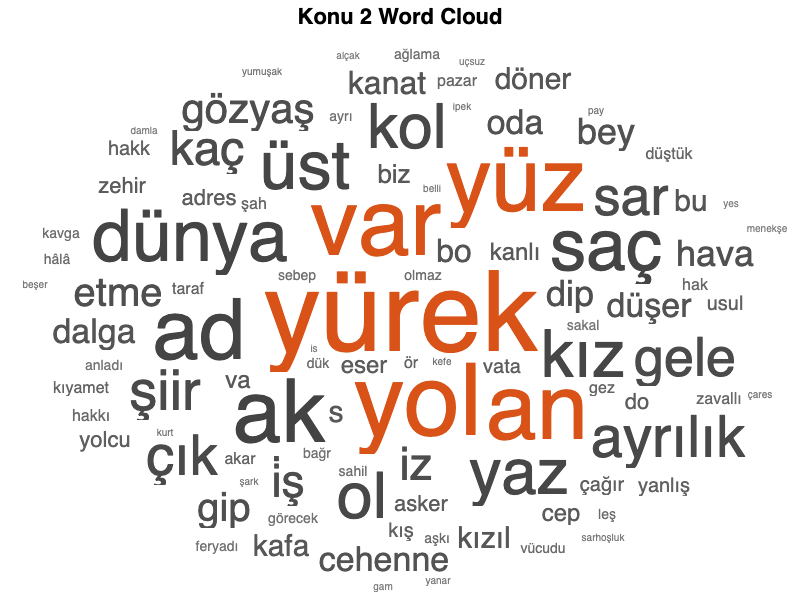

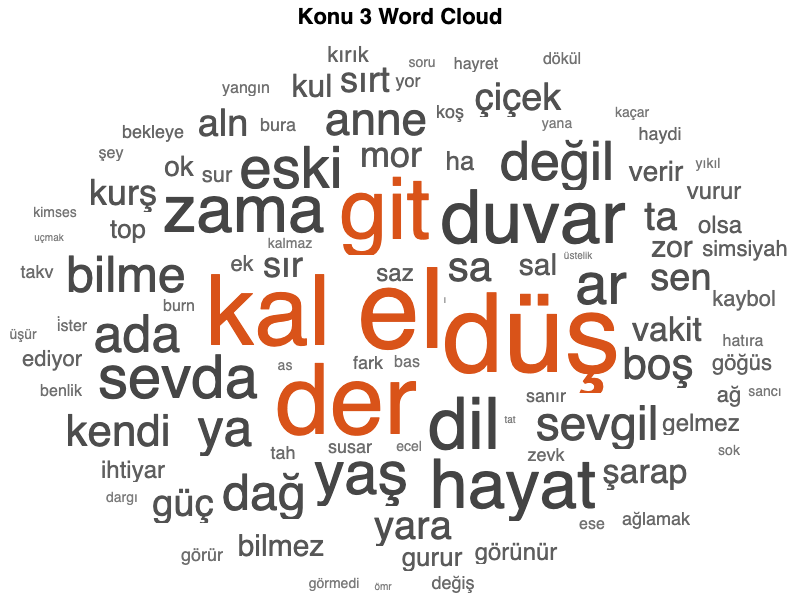

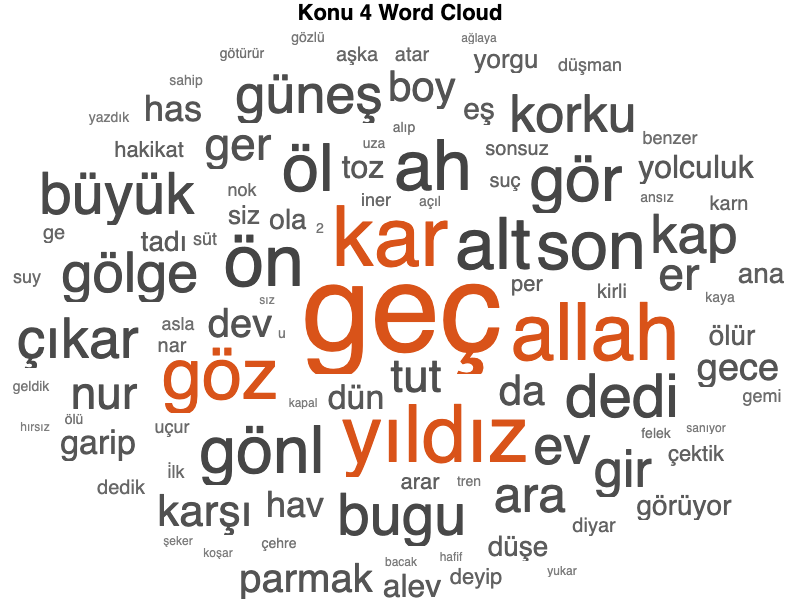

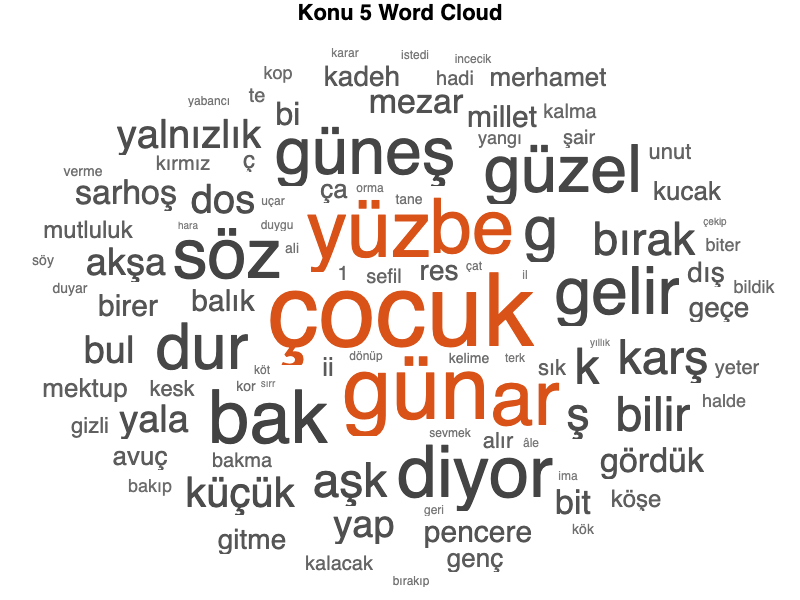

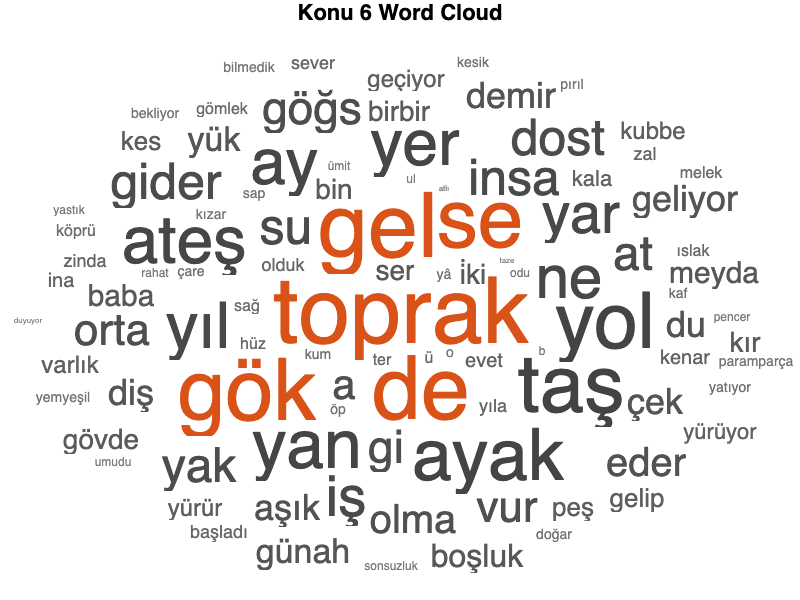

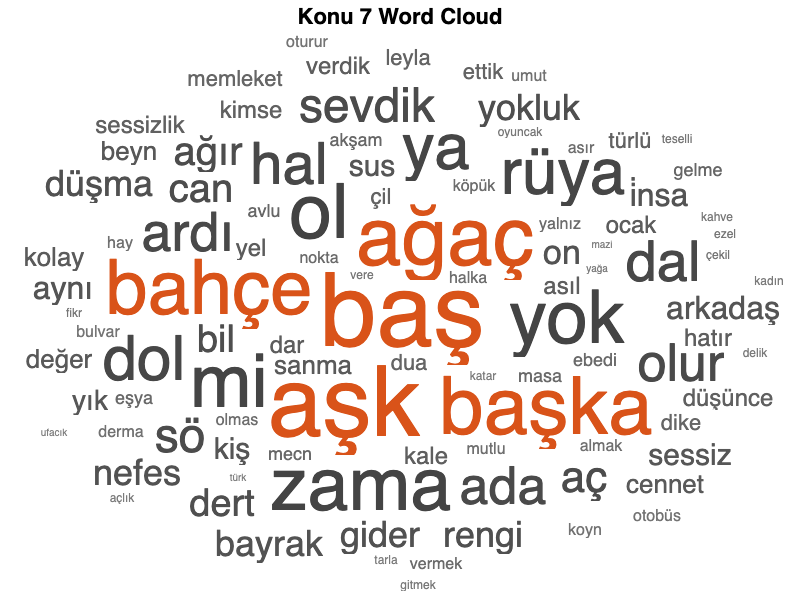

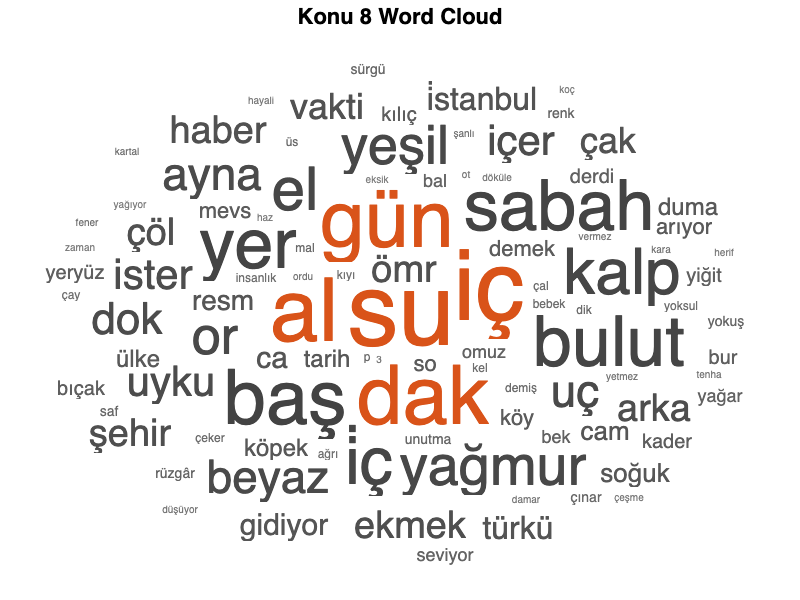

% To prepare wordcloud graphing to see the theme words at a glance.
for c = 1:NumberTopics
    fh = figure('Name', sprintf('Konu %d Word Cloud', c), ...
                'NumberTitle','off', ...
                'Position',[100 100 400 300]);  
    wordcloudgraph = wordcloud(mdl, c);
    wordcloudgraph.Title = sprintf('Konu %d Word Cloud', c);
    drawnow
end